clearvars
close all
clc

load('Hackam1969a_orig.mat')
R1_A = 0.155/2; %_cm
R1_B = 0.315/2; %_cm
R2_A = 1.714/2; %_cm
R2_B = 3.630/2; %_cm
p_atm = 6; %_Torr

%% corrected values 
p_A.cyl.CO2.H69{1} = Am_PRvsER296(:,1)*10; %_Torr
U_A.cyl.CO2.H69{1} = Am_PRvsER296(:,2)*10; %_V
p_A.cyl.CO2.H69{2} = Ap_PRvsER296(:,1)*10; %_Torr
U_A.cyl.CO2.H69{2} = Ap_PRvsER296(:,2)*10; %_V
p_A.cyl.CO2.H69{3} = Am_PRvsER364(:,1)*10; %_Torr
U_A.cyl.CO2.H69{3} = Am_PRvsER364(:,2)*10; %_V
p_A.cyl.CO2.H69{4} = Ap_PRvsER364(:,1)*10; %_Torr
U_A.cyl.CO2.H69{4} = Ap_PRvsER364(:,2)*10; %_V
p_A.cyl.CO2.H69{5} = Am_PRvsER468(:,1)*10; %_Torr
U_A.cyl.CO2.H69{5} = Am_PRvsER468(:,2)*10; %_V
p_A.cyl.CO2.H69{6} = Ap_PRvsER468(:,1)*10; %_Torr
U_A.cyl.CO2.H69{6} = Ap_PRvsER468(:,2)*10; %_V

p_B.cyl.CO2.H69{1} = Bm_PRvsER296(:,1)*10; %_Torr
U_B.cyl.CO2.H69{1} = Bm_PRvsER296(:,2)*10; %_V
p_B.cyl.CO2.H69{2} = Bp_PRvsER296(:,1)*10; %_Torr
U_B.cyl.CO2.H69{2} = Bp_PRvsER296(:,2)*10; %_V

pr_A.cyl.CO2.H69{1} = Am_PvsU296(:,1)/10; %_cm_Torr
Er_A.cyl.CO2.H69{1} = Am_PvsU296(:,2)/10; %_V
pr_A.cyl.CO2.H69{2} = Ap_PvsU296(:,1)/10; %_cm_Torr
Er_A.cyl.CO2.H69{2} = Ap_PvsU296(:,2)/10; %_V
pr_A.cyl.CO2.H69{3} = Am_PvsU364(:,1)/10; %_cm_Torr
Er_A.cyl.CO2.H69{3} = Am_PvsU364(:,2)/10; %_V
pr_A.cyl.CO2.H69{4} = Ap_PvsU364(:,1)/10; %_cm_Torr
Er_A.cyl.CO2.H69{4} = Ap_PvsU364(:,2)/10; %_V
pr_A.cyl.CO2.H69{5} = Am_PvsU468(:,1)/10; %_cm_Torr
Er_A.cyl.CO2.H69{5} = Am_PvsU468(:,2)/10; %_V
pr_A.cyl.CO2.H69{6} = Ap_PvsU468(:,1)/10; %_cm_Torr
Er_A.cyl.CO2.H69{6} = Ap_PvsU468(:,2)/10; %_V

pr_B.cyl.CO2.H69{1} = Bm_PvsU296(:,1)/10; %_cm_Torr
Er_B.cyl.CO2.H69{1} = Bm_PvsU296(:,2)/10; %_V
pr_B.cyl.CO2.H69{2} = Bp_PvsU296(:,1)/10; %_cm_Torr
Er_B.cyl.CO2.H69{2} = Bp_PvsU296(:,2)/10; %_V

clear A* B*

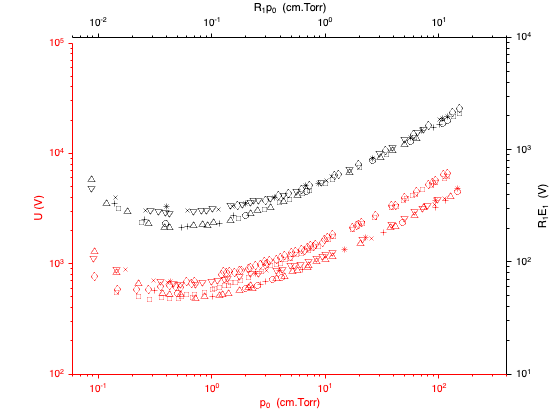

figure('Name','Hackam et al., 1969: Original Curves');

hold on
line(pr_A.cyl.CO2.H69{1} , Er_A.cyl.CO2.H69{1} , 'LineStyle','none', 'Color','k','Marker','^');
line(pr_A.cyl.CO2.H69{2} , Er_A.cyl.CO2.H69{2} , 'LineStyle','none', 'Color','k','Marker','v');
line(pr_A.cyl.CO2.H69{3} , Er_A.cyl.CO2.H69{3} , 'LineStyle','none', 'Color','k','Marker','o');
line(pr_A.cyl.CO2.H69{4} , Er_A.cyl.CO2.H69{4} , 'LineStyle','none', 'Color','k','Marker','*');
line(pr_A.cyl.CO2.H69{5} , Er_A.cyl.CO2.H69{5} , 'LineStyle','none', 'Color','k','Marker','+');
line(pr_A.cyl.CO2.H69{6} , Er_A.cyl.CO2.H69{6} , 'LineStyle','none', 'Color','k','Marker','x');
line(pr_B.cyl.CO2.H69{1} , Er_B.cyl.CO2.H69{1} , 'LineStyle','none', 'Color','k','Marker','s');
line(pr_B.cyl.CO2.H69{2} , Er_B.cyl.CO2.H69{2} , 'LineStyle','none', 'Color','k','Marker','d');
hold off
ax1 = gca;
ax1.XAxisLocation = "top";
ax1.YAxisLocation = "right";
ax1.TickDir      = 'out';

ax1.XColor       = 'k';
ax1.XMinorTick   = 'on';
ax1.XLabel.String = 'R_1p_0 (cm.Torr)';
ax1.XScale       = 'log';
ax1.XTick        = logspace(-2,2,5);
ax1.XLim         = [6e-3 40];

ax1.YColor       = 'k';
ax1.YMinorTick   = 'on';
ax1.YLabel.String = 'R_1E_1 (V)';
ax1.YScale       = 'log';
ax1.YTick        = logspace(1,4,4);
ax1.YLim         = [10 1e4];

ax2 = axes('Position',ax1.Position,'XAxisLocation','bottom','YAxisLocation','left','Color','none');
hold on
line(p_A.cyl.CO2.H69{1} , U_A.cyl.CO2.H69{1} , 'LineStyle','none', 'Color','r','Marker','^');
line(p_A.cyl.CO2.H69{2} , U_A.cyl.CO2.H69{2} , 'LineStyle','none', 'Color','r','Marker','v');
line(p_A.cyl.CO2.H69{3} , U_A.cyl.CO2.H69{3} , 'LineStyle','none', 'Color','r','Marker','o');
line(p_A.cyl.CO2.H69{4} , U_A.cyl.CO2.H69{4} , 'LineStyle','none', 'Color','r','Marker','*');
line(p_A.cyl.CO2.H69{5} , U_A.cyl.CO2.H69{5} , 'LineStyle','none', 'Color','r','Marker','+');
line(p_A.cyl.CO2.H69{6} , U_A.cyl.CO2.H69{6} , 'LineStyle','none', 'Color','r','Marker','x');
line(p_B.cyl.CO2.H69{1} , U_B.cyl.CO2.H69{1} , 'LineStyle','none', 'Color','r','Marker','s');
line(p_B.cyl.CO2.H69{2} , U_B.cyl.CO2.H69{2} , 'LineStyle','none', 'Color','r','Marker','d');
hold off

ax2.TickDir      = 'out';

ax2.XColor       = 'r';
ax2.XMinorTick   = 'on';
ax2.XLabel.String = 'p_0 (cm.Torr)';
ax2.XScale       = 'log';
ax2.XTick        = logspace(-1,3,5);
ax2.XLim         = [0.06 400];

ax2.YColor       = 'r';
ax2.YMinorTick   = 'on';
ax2.YLabel.String = 'U (V)';
ax2.YScale       = 'log';
ax2.YTick        = logspace(2,5,4);
ax2.YLim         = [1e2 1e5];

## Paschen

$p_{\rm atm}=6{\rm~Torr}$ for Mars


$$R_1p_0 = r_{\rm eq}p_{\rm atm}\Rightarrow r_{\rm eq} = \frac{R_1p_0}{p_{\rm atm}}\quad{\rm in}\quad\frac{\rm[cm][Torr]}{\rm[Torr]}={\rm [cm]}$$



$$R_1E_1 = r_{\rm eq}\cdot E_{\rm cr} \Rightarrow E_{\rm cr} = \frac{R_1E_1}{r_{\rm eq}} = \frac{R_1E_1}{R_1p_0}p_{\rm atm} \quad{\rm in}\quad\frac{\rm[V]}{\rm[cm][Torr]}{\rm[Torr]}=\frac{\rm[V]}{\rm [cm]}$$


figure;%('Name','Hackam et al., 1969: Paschen Curves');
cm    = 10^-2; %_m
kV_cm = 1.0e5; %_V/_m
d.cyl.CO2.H69{1}   = pr_A.cyl.CO2.H69{1}/p_atm*cm; %_m
d.cyl.CO2.H69{2}   = pr_A.cyl.CO2.H69{2}/p_atm*cm; %_m
d.cyl.CO2.H69{3}   = pr_A.cyl.CO2.H69{3}/p_atm*cm; %_m
d.cyl.CO2.H69{4}   = pr_A.cyl.CO2.H69{4}/p_atm*cm; %_m
d.cyl.CO2.H69{5}   = pr_A.cyl.CO2.H69{5}/p_atm*cm; %_m
d.cyl.CO2.H69{6}   = pr_A.cyl.CO2.H69{6}/p_atm*cm; %_m
d.cyl.CO2.H69{7}   = pr_B.cyl.CO2.H69{1}/p_atm*cm; %_m
d.cyl.CO2.H69{8}   = pr_B.cyl.CO2.H69{2}/p_atm*cm; %_m
Ecr.cyl.CO2.H69{1} = Er_A.cyl.CO2.H69{1}./pr_A.cyl.CO2.H69{1}*p_atm/cm; % _V/_m
Ecr.cyl.CO2.H69{2} = Er_A.cyl.CO2.H69{2}./pr_A.cyl.CO2.H69{2}*p_atm/cm; % _V/_m
Ecr.cyl.CO2.H69{3} = Er_A.cyl.CO2.H69{3}./pr_A.cyl.CO2.H69{3}*p_atm/cm; % _V/_m
Ecr.cyl.CO2.H69{4} = Er_A.cyl.CO2.H69{4}./pr_A.cyl.CO2.H69{4}*p_atm/cm; % _V/_m
Ecr.cyl.CO2.H69{5} = Er_A.cyl.CO2.H69{5}./pr_A.cyl.CO2.H69{5}*p_atm/cm; % _V/_m
Ecr.cyl.CO2.H69{6} = Er_A.cyl.CO2.H69{6}./pr_A.cyl.CO2.H69{6}*p_atm/cm; % _V/_m
Ecr.cyl.CO2.H69{7} = Er_B.cyl.CO2.H69{1}./pr_B.cyl.CO2.H69{1}*p_atm/cm; % _V/_m
Ecr.cyl.CO2.H69{8} = Er_B.cyl.CO2.H69{2}./pr_B.cyl.CO2.H69{2}*p_atm/cm; % _V/_m

A.R1p0 = pr_A.cyl.CO2.H69{:}; %_cm_Torr
B.R1p0 = pr_B.cyl.CO2.H69{:}; %_cm_Torr
A.R1E1 = Er_A.cyl.CO2.H69{:}; %_V
B.R1E1 = Er_B.cyl.CO2.H69{:}; %_V

R1p0 = [A.R1p0;B.R1p0]

R1p0 =     0.0088
    0.0117
    0.0180
    0.0280
    0.0386
    0.0425
    0.0691
    0.0823
    0.0916
    0.1033


E1_p0 = [A.R1E1./A.R1p0;B.R1E1./B.R1p0]

E1_p0 = 1.0e+04 *

    6.2319
    2.8098
    1.5499
    0.7901
    0.5219
    0.4761
    0.3050
    0.2609
    0.2304
    0.2162


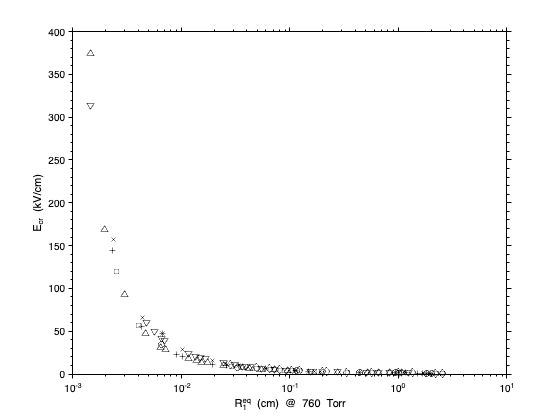


plot(...
    d.cyl.CO2.H69{1}/cm , Ecr.cyl.CO2.H69{1}/kV_cm, 'k^',...
    d.cyl.CO2.H69{2}/cm , Ecr.cyl.CO2.H69{2}/kV_cm, 'kv',...
    d.cyl.CO2.H69{3}/cm , Ecr.cyl.CO2.H69{3}/kV_cm, 'ko',...
    d.cyl.CO2.H69{4}/cm , Ecr.cyl.CO2.H69{4}/kV_cm, 'k*',...
    d.cyl.CO2.H69{5}/cm , Ecr.cyl.CO2.H69{5}/kV_cm, 'k+',...
    d.cyl.CO2.H69{6}/cm , Ecr.cyl.CO2.H69{6}/kV_cm, 'kx',...
    d.cyl.CO2.H69{7}/cm , Ecr.cyl.CO2.H69{7}/kV_cm, 'ks',...
    d.cyl.CO2.H69{8}/cm , Ecr.cyl.CO2.H69{8}/kV_cm, 'kd');
ax1 = gca;
ax1.XAxisLocation = "bottom";
ax1.YAxisLocation = "left";
ax1.TickDir      = 'out';

ax1.XColor       = 'k';
ax1.XMinorTick   = 'on';
ax1.XLabel.String = 'R_1^{eq} (cm) @ 760 Torr';
ax1.XScale       = 'log';
% ax1.XTick        = logspace(-5,-1,5);
% ax1.XLim         = [1e-5 1e-1];

ax1.YColor       = 'k';
ax1.YMinorTick   = 'on';
ax1.YLabel.String = 'E_{cr} (kV/cm)';
ax1.YScale       = 'lin';

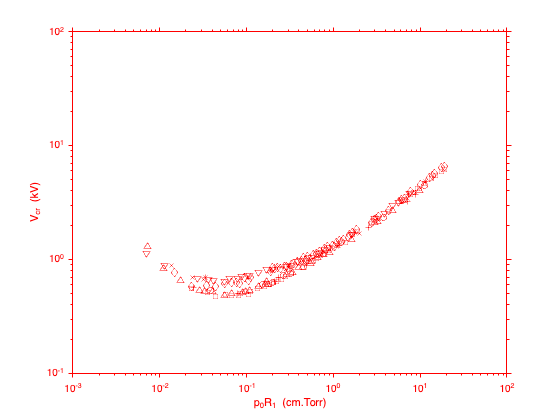


figure;

pd.cyl.CO2.H69{1}  = p_A.cyl.CO2.H69{1}*R1_A;
pd.cyl.CO2.H69{2}  = p_A.cyl.CO2.H69{2}*R1_A;
pd.cyl.CO2.H69{3}  = p_A.cyl.CO2.H69{3}*R1_A;
pd.cyl.CO2.H69{4}  = p_A.cyl.CO2.H69{4}*R1_A;
pd.cyl.CO2.H69{5}  = p_A.cyl.CO2.H69{5}*R1_A;
pd.cyl.CO2.H69{6}  = p_A.cyl.CO2.H69{6}*R1_A;
pd.cyl.CO2.H69{7}  = p_B.cyl.CO2.H69{1}*R1_B;
pd.cyl.CO2.H69{8}  = p_B.cyl.CO2.H69{2}*R1_B;

Vcr.cyl.CO2.H69{1} = U_A.cyl.CO2.H69{1};
Vcr.cyl.CO2.H69{2} = U_A.cyl.CO2.H69{2};
Vcr.cyl.CO2.H69{3} = U_A.cyl.CO2.H69{3};
Vcr.cyl.CO2.H69{4} = U_A.cyl.CO2.H69{4};
Vcr.cyl.CO2.H69{5} = U_A.cyl.CO2.H69{5};
Vcr.cyl.CO2.H69{6} = U_A.cyl.CO2.H69{6};
Vcr.cyl.CO2.H69{7} = U_B.cyl.CO2.H69{1};
Vcr.cyl.CO2.H69{8} = U_B.cyl.CO2.H69{2};

ax2 = axes('Position',ax1.Position,'XAxisLocation','bottom','YAxisLocation','left','Color','none');
plot( ...
    pd.cyl.CO2.H69{1} , Vcr.cyl.CO2.H69{1}*1e-3 , 'r^',...
    pd.cyl.CO2.H69{2} , Vcr.cyl.CO2.H69{2}*1e-3 , 'rv',...
    pd.cyl.CO2.H69{3} , Vcr.cyl.CO2.H69{3}*1e-3 , 'ro',...
    pd.cyl.CO2.H69{4} , Vcr.cyl.CO2.H69{4}*1e-3 , 'r*',...
    pd.cyl.CO2.H69{5} , Vcr.cyl.CO2.H69{5}*1e-3 , 'r+',...
    pd.cyl.CO2.H69{6} , Vcr.cyl.CO2.H69{6}*1e-3 , 'rx',...
    pd.cyl.CO2.H69{7} , Vcr.cyl.CO2.H69{7}*1e-3 , 'rs',...
    pd.cyl.CO2.H69{8} , Vcr.cyl.CO2.H69{8}*1e-3 , 'rd');
hold off

ax2.TickDir      = 'out';

ax2.XColor       = 'r';
ax2.XMinorTick   = 'on';
ax2.XLabel.String = 'p_0R_1 (cm.Torr)';
ax2.XScale       = 'log';
ax2.XTick        = logspace(-3,2,6);
ax2.XLim         = [1e-3 1e2];

ax2.YColor       = 'r';
ax2.YMinorTick   = 'on';
ax2.YLabel.String = 'V_{cr} (kV)';
ax2.YScale       = 'log';
ax2.YTick        = logspace(-1,2,4);
ax2.YLim         = [1e-1 1e2];


clear A* B* pr_* p_* R1_* R2_* U_* Er_* ax* p0 cm kV_cm 
save('Hackam1969a_sorted.mat')
